# Finite Difference Method - 2D Poisson Equation

Use the FDM to solve Poisson's equation on a rectangular domain

## Step 0: preliminaries

Create and visualize a 11x21 grid using the meshgrid function

x = linspace(0,1,11);
y = linspace(0,1,21);
[X,Y] = meshgrid(x,y);
plot(X,Y,'.')
X % Each row represents the x-values across the 2D grid for a specific value of y-value

X =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000
         0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000
         0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000
         0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000
         0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000
         0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000
         0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000
         0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000
         0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.00

Y % Each column represents y-coordinates across the 2D grid for a specific value of x

Y =          0         0         0         0         0         0         0         0         0         0         0
    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500
    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000
    0.1500    0.1500    0.1500    0.1500    0.1500    0.1500    0.1500    0.1500    0.1500    0.1500    0.1500
    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000
    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500
    0.3000    0.3000    0.3000    0.3000    0.3000    0.3000    0.3000    0.3000    0.3000    0.3000    0.3000
    0.3500    0.3500    0.3500    0.3500    0.3500    0.3500    0.3500    0.3500    0.3500    0.3500    0.3500
    0.4000    0.4000    0.4000    0.4000    0.4000    0.4000    0.4000    0.4000    0.4000    0.4000    0.40

## Step 1: Dirichlet BCs


$$    \left\{
     \begin{array}{l}
\frac{\partial^2\varphi}{\partial x^2} + \frac{\partial^2\varphi}{\partial y^2} - t(x)= 0 \\
\varphi(x,0) = \varphi_S \qquad \mathrm{South \ edge} \\
\varphi(0,y) = \varphi_W \quad \mathrm{West \ edge} \\
\varphi(L_x,y) = \varphi_E \quad \mathrm{East \ edge} \\ 
\varphi(x,L_y) = \varphi_N \quad \mathrm{North \ edge} \\
\end{array}$$


Create an m-function "FDM_2D_s1" with the following I/O scheme:

- input: geometry ($x_0$,$L_x$, $y_0$, $L_y$, number of nodes in the x and y-directions); boundary conditions (boundary condition type and value on S-W-N-E edges); uniform source term $t(x)=t$

- output: X,Y ("meshgridded" nodal coordinates), phi (computed values of unknown function)

Use the function to simulate a case where $n_x = 25; n_y = 25; t = -1
$ and zero Dirichlet BCs on all edges.

geom.nx = 15;
geom.ny = 15;
geom.Lx = 1;
geom.Ly = 1;

t = -1;

[phi,x,y] = FDM_2D_s1(geom,t); % solve

% plot
surf(x,y,reshape(phi,geom.nx,geom.ny));
xlabel('x'); ylabel('y'); colorbar

Compare to analycal solution obtained for a unit square domain with zero Dirichlet BCs:


$$\varphi_{\mathrm{analytical}} = \sin(\pi x) \sin(\pi y)$$


Which is obtained for


$$t(x, y) = -\pi^2 \sin(\pi x) \sin(\pi y)$$


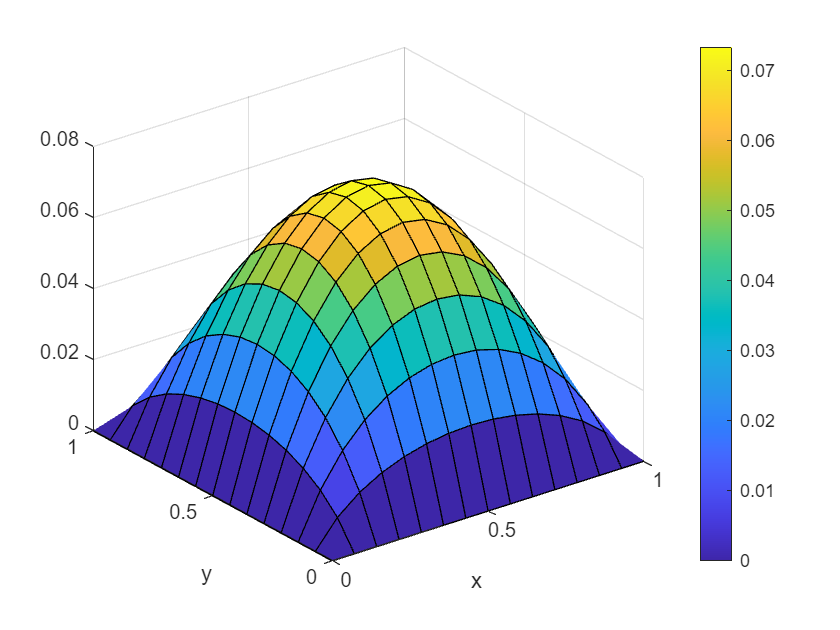

geom.nx = 40;
geom.ny = 40;


% numerical solution
t = @(x,y) -2*pi^2*sin(pi*x) .* sin(pi*y);
[phi,x,y] = FDM_2D_s1(geom,t);

[X,Y] = meshgrid(x,y);
phi_exact = sin(pi * X) .* sin(pi * Y);

phi = reshape(phi,geom.ny,geom.nx);
err = (phi-phi_exact);

surf(x,y,err); colorbar; title('error');

Perform a convergence test using the grid_sizes = [10, 20, 40, 80].

grid_sizes = [10, 20, 40, 80];  % Example grid sizes
errors = zeros(size(grid_sizes));

for k = 1:length(grid_sizes)
    % Set up geometry for this grid size
    geom.nx = grid_sizes(k);
    geom.ny = grid_sizes(k);
    
    [phi,x,y] = FDM_2D_s1(geom, t); % numerical solution

    % Compute the exact solution
    [X,Y] = meshgrid(x,y);
    phi_exact = sin(pi * X) .* sin(pi * Y);
    
    % Compute the Euclidean norm of the error
    err = phi-phi_exact(:);
    errors(k) = sqrt(mean((phi(:) - phi_exact(:)).^2)); % norm(err);
end

% Check convergence rate
for k = 2:length(grid_sizes)

    err_1 = errors(k-1);
    err_2 = errors(k);

    h_1 = 1/grid_sizes(k-1);
    h_2 = 1/grid_sizes(k);

    rate = log(err_1/err_2) / log(h_1/h_2);
    fprintf('Grid size: %dx%d, Error: %.5e, Convergence Rate: %.2f\n', ...
            grid_sizes(k), grid_sizes(k), errors(k), rate);
end

Grid size: 20x20, Error: 1.08367e-03, Convergence Rate: 2.08
Grid size: 40x40, Error: 2.63697e-04, Convergence Rate: 2.04
Grid size: 80x80, Error: 6.50737e-05, Convergence Rate: 2.02


## Step 2: Dirichlet and Neumann BCs


$$    \left\{
     \begin{array}{l}
\frac{\partial^2\varphi}{\partial x^2} + \frac{\partial^2\varphi}{\partial y^2} - t(x)= 0 \\
\varphi(x,0) = \varphi_S \qquad \mathrm{South \ edge} \\
\varphi(0,y) = \varphi_W \quad \mathrm{West \ edge} \\
\frac{\partial \varphi}{\partial x}|_E = \varphi'_E \quad \mathrm{East \ edge} \\ 
\frac{\partial \varphi}{\partial y}|_N = \varphi'_N \quad \mathrm{North \ edge} \\
\end{array}$$


Create an m-function "FDM_2D_s2" that allows Neumann boundary conditions on the East and North edges

Use the function to simulate a case where $n_x = 25; n_y = 25; \varphi_S = 1; \varphi_W = 0; \varphi'_N = 0; \varphi'_W = 0; t = 1
$